### **Projekt: Situation Understanding**

## **Implementierung eines Extended Kalman Filters für die Positionsschätzung eines aufsteigenden Helikopters. **

Für diese Projekt wird ein Helikopter, welcher von dem Boden aus aufsteigt, simuliert. Der Helikopter fliegt dabei in einer Art spirale. Die Bewegungsgleichung dieses Helikopters wird in dem folgenden Codeabschnitt definiert. Um den Helikopter mit Sensnoren zu erfassen, werden zwei Radarsensoren definiert, welche die Bewegungen des Helikopters mit Polarkoordinaten messen.

% Initialisierung der Zustandsvariablen
R_0 = [0; 0; 0];  % Anfangsposition (Nullvektor)
V_0 = [0; 0; 0];  % Anfangsgeschwindigkeit (Nullvektor)

% Zeitbereich auf eine Minute erweitern
t = linspace(0, 120, 240);

% Beschleunigung in x-, y- und z-Richtung in Abhängigkeit von der Zeit t
A = [1 * cos(t/12); 0.5 * sin(t/12); 0.05 * ones(size(t/12))];

% Geschwindigkeit in x-, y- und z-Richtung in Abhängigkeit von der Zeit t
V = cumtrapz(t/12, A, 2) + V_0;

% Position in x-, y- und z-Richtung in Abhängigkeit von der Zeit t
R_pos = R_0 + cumtrapz(t/12, V, 2) + 0.5 * cumtrapz(t/12, A, 2) .* t;

% Anzahl der Zeitschritte
N = length(t);

% Radarpositionen
pos_radar1 = [0, -10, 0];
pos_radar2 = [-50, 30, 0];

% Zustandsvektor x_k (6-dimensional: [x, y, z, vx, vy, vz])
x_k = [R_pos(1,:); R_pos(2,:); R_pos(3,:); V(1,:); V(2,:); V(3,:)];


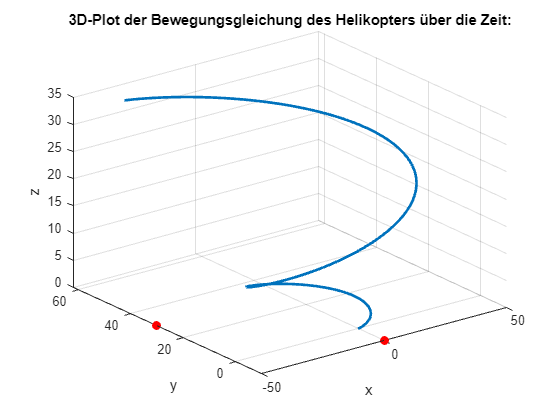

figure;
hold on;  % Aktiviert den "hold on"-Modus, um mehrere Plots in derselben Figur zu zeichnen
plot3(R_pos(1,:), R_pos(2,:), R_pos(3,:), 'LineWidth', 2);  % Zeichnet den 3D-Plot der Daten R mit Linienbreite 2

% Zeichnet den Punkt für Radar 1 in Rot mit einem Marker der Größe 20
plot3(pos_radar1(1), pos_radar1(2), pos_radar1(3), 'r.', 'MarkerSize', 20);
% Zeichnet den Punkt für Radar 2 in Rot mit einem Marker der Größe 20
plot3(pos_radar2(1), pos_radar2(2), pos_radar2(3), 'r.', 'MarkerSize', 20);
title('3D-Plot der Bewegungsgleichung des Helikopters über die Zeit:');
xlabel('x');
ylabel('y');
zlabel('z');
grid on;
view(3);
hold off;

% Prozessrauschkovarianzmatrix Q        (Annahme: Prozessrauschen ist 0, da wir noch keine weiteren Informationen haben)
Q = eye(6) * 0.1;

% Messrauschkovarianzmatrix R (Annahme: gleiche Varianzen für alle Beobachtungen)
standardabweichung_x = 0.7;  % Standardabweichung in x-Richtung
standardabweichung_y = 0.7;  % Standardabweichung in y-Richtung
standardabweichung_z = 0.7;  % Standardabweichung in z-Richtung

R = diag([standardabweichung_x^2, standardabweichung_y^2, standardabweichung_z^2, ...
          standardabweichung_x^2, standardabweichung_y^2, standardabweichung_z^2]);



% Zustandsübergangsmatrix F (Identity matrix as we assume constant velocity)
% Zeitschrittgröße
dt = t(2) - t(1);

% Zustandsübergangsmatrix F
F = [1 0    2.5*dt^2      2*dt^2      dt          2*dt;
     0 1    0           0.5*dt      0.125*dt^2    0;
     0 0    1           0.25*dt^2    0           0;
     0 0    0           1           0           0;
     0 0    0           0           1           0.5*dt^2;
     0 0    0           0           0           1]; 

% Schätzung der Anfangsvarianz des Zustandsvektors (Annahme: großer Wert, da wir wenig über den Anfangszustand wissen)
P = 1*eye(6);

z_m = [];
x_m = [];
% messungen erstellen
for i = 2:N
        
        % Es gibt ein Rauschen bei den Radarmessungen welches in x,y,z Richtung jeweils um +/- 0.5 Meter ausmachen kann.
        % Das Rauschen ist dabei für beiden Sensoren das Gleiche.
        zufallswerte_x = rand(1, 1) - 0.5;
        zufallswerte_y = rand(1, 1) - 0.5;
        zufallswerte_z = rand(1, 1) - 0.5;
        
        % Scale and shift the values to the range between -0.25 and 0.25
        zufallswerte_x = zufallswerte_x * standardabweichung_x;
        zufallswerte_y = zufallswerte_y * standardabweichung_y;
        zufallswerte_z = zufallswerte_z * standardabweichung_z;

        x_x2 = x_k(1,i) + zufallswerte_x;
        x_y2 = x_k(2,i) + zufallswerte_y;
        x_z2 = x_k(3,i) + zufallswerte_z;
        x_x1 = x_k(1,i) + zufallswerte_x;
        x_y1 = x_k(2,i) + zufallswerte_y;
        x_z1 = x_k(3,i) + zufallswerte_z;
        x_noise = [x_x1; x_y1;x_z1;x_x2;x_y2;x_z2];
        x_noise2 = [x_x2;x_y2;x_z2];
        %z = [calculate_observations(x_k(:, i), pos_radar1); calculate_observations(x_k(:, i), pos_radar2)];
        z = [calculate_observations(x_noise, pos_radar1); calculate_observations(x_noise2, pos_radar2)];
        z_m = [z_m, z];
    
end
z_m

z_m =     9.9058   10.3480   10.2770    9.9231   10.3003   10.0203   10.2933   10.0924   10.1637   10.1400   10.1592   10.3580   10.3777   10.6445   10.9671   10.5020   11.3390   10.7575   10.9813   11.6494   11.8726   12.1391   12.0389   12.8451   13.0814   13.7151   13.7959   14.1881   14.2294   15.0870   15.2231   15.4786   16.1138   16.7901   16.8897   17.2319   17.8481   18.3523   18.8909   19.1060   19.7545   20.2296   21.1088   21.1140   21.2682   21.9506   22.6421   23.0015   22.9436   23.3549
   90.8250   90.4342   90.6890   87.7540   87.8521   89.3444   85.5753   86.0253   86.3056   82.8429   82.4849   79.9064   80.2810   79.8359   75.7218   74.3643   73.7944   73.4746   71.4421   69.5898   68.7527   65.3920   66.3399   64.2340   61.8604   62.0215   59.5082   60.2652   58.8964   59.5685   57.5544   57.0795   56.1919   56.6007   55.3966   55.3543   55.1614   55.3988   55.2342   54.5258   55.6278   54.3762   55.2514   56.0342   55.7870   56.6849   56.5454   57.3939   57.9945   

**Geschätze Position im Vergleich zur tatsächlichen Position:**

messung_kartesisch = get_kartesische_Koordianten(z_m);


% Plot der geschätzten Position in 3D-Raum
figure(1);
plot3(R_pos(1,:), R_pos(2,:), R_pos(3,:), 'LineWidth', 2);
hold on;
plot3(messung_kartesisch(1, :), messung_kartesisch(2, :), messung_kartesisch(3, :), 'r.', 'MarkerSize', 7);
plot3(pos_radar1(1), pos_radar1(2), pos_radar1(3), 'r.', 'MarkerSize', 20);
plot3(pos_radar2(1), pos_radar2(2), pos_radar2(3), 'r.', 'MarkerSize', 20);
title('3D-Plot der wahren Positionen im Verlgeich zu den Messung des ersten Radars:');
xlabel('x');
ylabel('y');
zlabel('z');
view()

ans =     0.7934   -0.6088         0   -0.0923
    0.3044    0.3967    0.8660   -0.7835
    0.5272    0.6871   -0.5000    8.3031
         0         0         0    1.0000


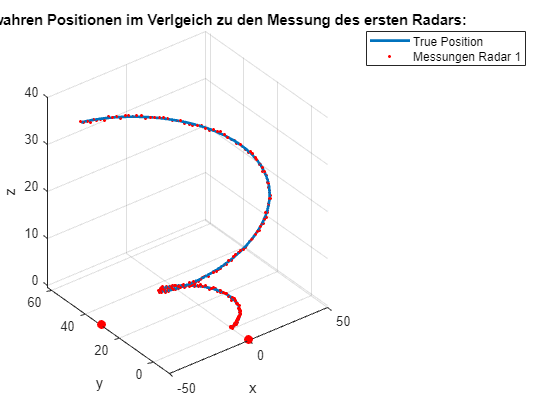

grid on;
view(3);
hold off;
legend('True Position','Messungen Radar 1');


% Plot der geschätzten Position in 3D-Raum
figure(1);
plot3(R_pos(1,:), R_pos(2,:), R_pos(3,:), 'LineWidth', 2);
hold on;
plot3(messung_kartesisch(4, :), messung_kartesisch(5, :), messung_kartesisch(6, :), 'g.', 'MarkerSize', 7);
plot3(pos_radar1(1), pos_radar1(2), pos_radar1(3), 'r.', 'MarkerSize', 20);
plot3(pos_radar2(1), pos_radar2(2), pos_radar2(3), 'r.', 'MarkerSize', 20);
title('3D-Plot der wahren Positionen im Verlgeich zu den Messung des zweiten Radars:');
xlabel('x');
ylabel('y');
zlabel('z');
view()

ans =     0.7934   -0.6088         0   -0.0923
    0.3044    0.3967    0.8660   -0.7835
    0.5272    0.6871   -0.5000    8.3031
         0         0         0    1.0000


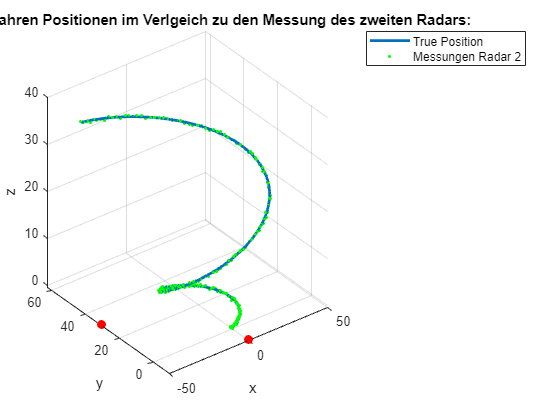

grid on;
view(3);
hold off;
legend('True Position','Messungen Radar 2');

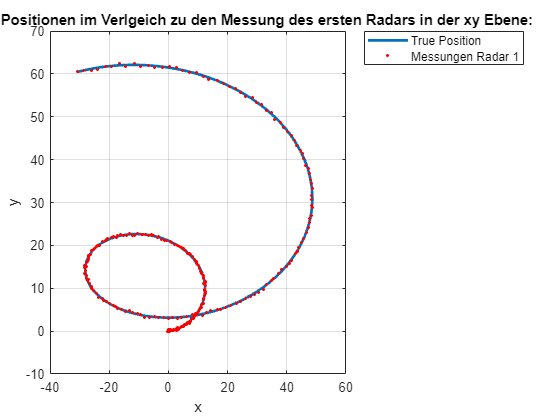



% Plot der geschätzten Position in 3D-Raum
figure(1);
plot(R_pos(1,:), R_pos(2,:), 'LineWidth', 2);
hold on;
plot(messung_kartesisch(1, :), messung_kartesisch(2, :), 'r.', 'MarkerSize', 7);
hold off;
title('3D-Plot der wahren Positionen im Verlgeich zu den Messung des ersten Radars in der xy Ebene:');
xlabel('x');
ylabel('y');
grid on;
legend('True Position','Messungen Radar 1');

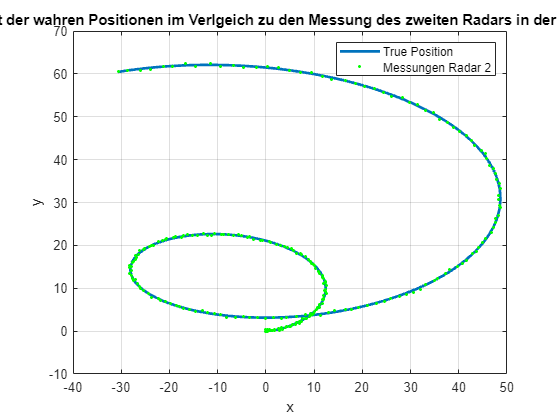


% Plot der geschätzten Position in 3D-Raum
figure(1);
plot(R_pos(1,:), R_pos(2,:), 'LineWidth', 2);
hold on;
plot(messung_kartesisch(4, :), messung_kartesisch(5, :), 'g.', 'MarkerSize', 7);
hold off;
title('3D-Plot der wahren Positionen im Verlgeich zu den Messung des zweiten Radars in der xy Ebene:');
xlabel('x');
ylabel('y');
grid on;
legend('True Position','Messungen Radar 2');

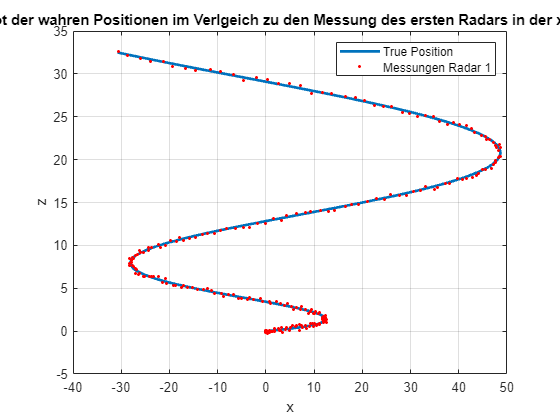



figure(1);
plot(R_pos(1,:), R_pos(3,:), 'LineWidth', 2);
hold on;
plot(messung_kartesisch(1, :), messung_kartesisch(3, :), 'r.', 'MarkerSize', 7);
hold off;
title('3D-Plot der wahren Positionen im Verlgeich zu den Messung des ersten Radars in der xz Ebene:');
xlabel('x');
ylabel('z');
grid on;
legend('True Position','Messungen Radar 1');

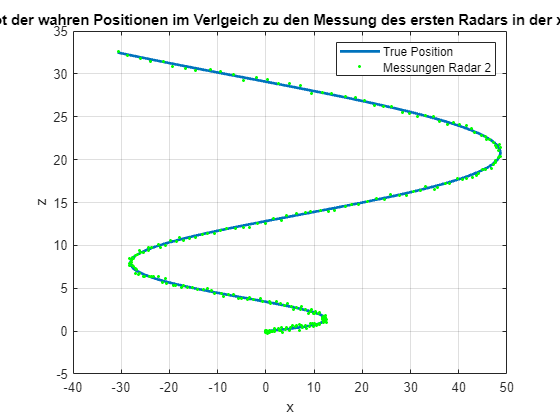


figure(1);
plot(R_pos(1,:), R_pos(3,:), 'LineWidth', 2);
hold on;
plot(messung_kartesisch(4, :), messung_kartesisch(6, :), 'g.', 'MarkerSize', 7);
hold off;
title('3D-Plot der wahren Positionen im Verlgeich zu den Messung des ersten Radars in der xz Ebene:');
xlabel('x');
ylabel('z');
grid on;
legend('True Position','Messungen Radar 2');

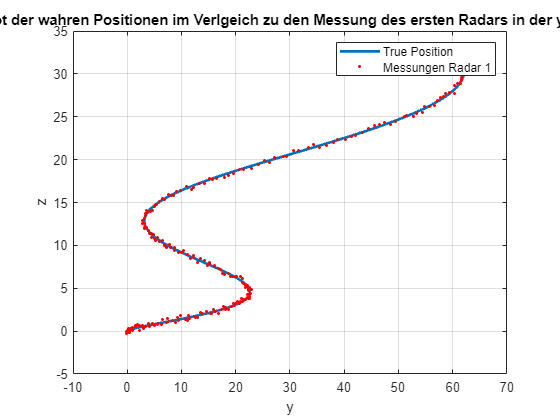




figure(1);
plot(R_pos(2,:), R_pos(3,:), 'LineWidth', 2);
hold on;
plot(messung_kartesisch(2, :), messung_kartesisch(3, :), 'r.', 'MarkerSize', 7);
hold off;
xlabel('y');
ylabel('z');
grid on;
title('3D-Plot der wahren Positionen im Verlgeich zu den Messung des ersten Radars in der yz Ebene:');
legend('True Position','Messungen Radar 1');

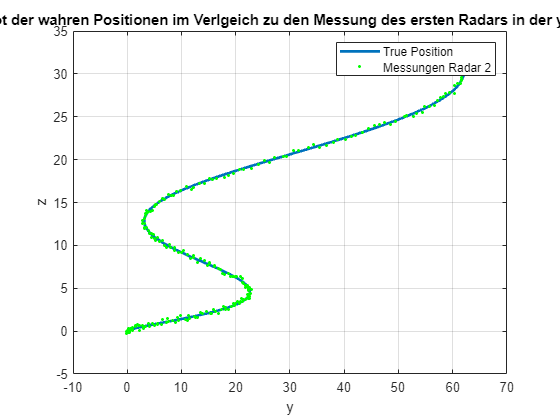


figure(1);
plot(R_pos(2,:), R_pos(3,:), 'LineWidth', 2);
hold on;
plot(messung_kartesisch(5, :), messung_kartesisch(6, :), 'g.', 'MarkerSize', 7);
hold off;
xlabel('y');
ylabel('z');
grid on;
title('3D-Plot der wahren Positionen im Verlgeich zu den Messung des ersten Radars in der yz Ebene:');
legend('True Position','Messungen Radar 2');

% EKF-Schätzung
for k = 2:N
    % Vorhersage
    x_k_pred = F * x_k(:, k-1);
    P_pred = F * P * F' + Q;
    % Update (Kalman Gain)
    H = create_observation_matrix(x_k_pred, pos_radar1, pos_radar2);
    K = P_pred * H' * inv(H * P_pred * H' + R);
    
    % Messungen
    %z_k = [calculate_observations(x_k(:, k), pos_radar1); calculate_observations(x_k(:, k), pos_radar2)];
    z_k = z_m(:,k-1);

    messungen = [messungen, z_k];
    % Update der Zustandsschätzung und Fehlerkovarianz
    x_k(:, k) = x_k_pred + K * (z_k - [calculate_observations(x_k_pred, pos_radar1); calculate_observations(x_k_pred, pos_radar2)]);
    P = (eye(6) - K * H) * P_pred;
end

% Geschätzte Position des Helikopters
estimated_position = x_k(1:3, :)

estimated_position =          0   -0.2100   -0.0213   -0.2020    0.9168   -0.1280    0.2530    0.9634    0.5460    0.6375    1.5108    1.1614    1.9309    1.5080    1.8794    2.7431    2.8753    2.9519    3.1649    3.6017    3.9240    4.1498    5.0573    4.8062    5.4118    6.1079    6.2560    6.9792    7.0410    7.3884    7.4831    8.1120    8.4541    8.8787    9.0971    9.5659    9.8285   10.1027   10.3571   10.6938   11.0794   11.1427   11.6079   11.8825   11.8628   11.9793   11.9633   12.2856   12.3554   12.3006
         0   -0.0797    0.1579    0.2114    0.0755    0.2422    0.1399    0.1795    0.1631    0.1609    0.0781    0.1245    0.1127    0.2612    0.3605    0.4473    0.3185    0.6561    0.5041    0.4186    0.6852    0.9448    0.9274    1.1613    1.3892    1.4622    1.9536    1.9175    2.2661    2.2750    2.8200    2.8599    2.9914    3.2882    3.8561    3.9634    4.1706    4.5561    4.9886    5.4136    5.6044    6.1545    6.4538    7.1145    7.5177    7.6804    8.2025    8.72

% Funktion zur Berechnung der Beobachtungen (Messmodell)

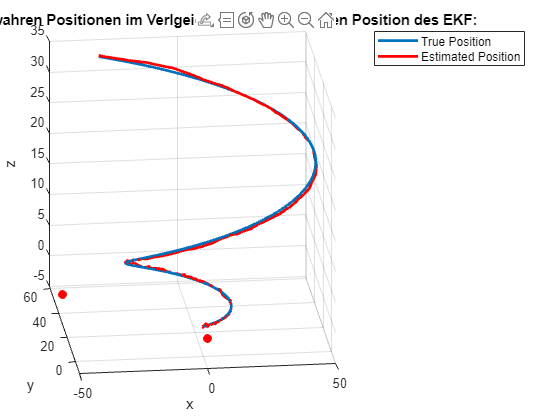

% Plot der geschätzten Position in 3D-Raum
figure(1);
plot3(R_pos(1,:), R_pos(2,:), R_pos(3,:), 'LineWidth', 2);
hold on;
plot3(estimated_position(1, :), estimated_position(2, :), estimated_position(3, :), 'r', 'LineWidth', 2);
plot3(pos_radar1(1), pos_radar1(2), pos_radar1(3), 'r.', 'MarkerSize', 20);
plot3(pos_radar2(1), pos_radar2(2), pos_radar2(3), 'r.', 'MarkerSize', 20);
hold off;
title('3D-Plot der wahren Positionen im Verlgeich zu der geschätzten Position des EKF:');
xlabel('x');
ylabel('y');
zlabel('z');
grid on;
legend('True Position', 'Estimated Position');

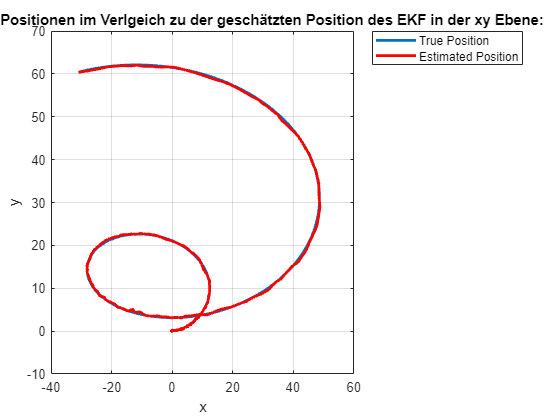


% Plot der geschätzten Position in 3D-Raum
figure(1);
plot(R_pos(1,:), R_pos(2,:), 'LineWidth', 2);
hold on;
plot(estimated_position(1, :), estimated_position(2, :), 'r', 'LineWidth', 2);
hold off;
title('3D-Plot der wahren Positionen im Verlgeich zu der geschätzten Position des EKF in der xy Ebene:');
xlabel('x');
ylabel('y');
grid on;
legend('True Position', 'Estimated Position');

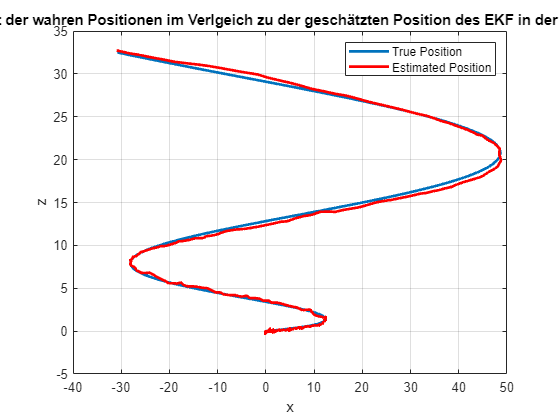


figure(1);
plot(R_pos(1,:), R_pos(3,:), 'LineWidth', 2);
hold on;
plot(estimated_position(1, :), estimated_position(3, :), 'r', 'LineWidth', 2);
hold off;
xlabel('x');
ylabel('z');
grid on;
title('3D-Plot der wahren Positionen im Verlgeich zu der geschätzten Position des EKF in der xz Ebene:');
legend('True Position', 'Estimated Position');

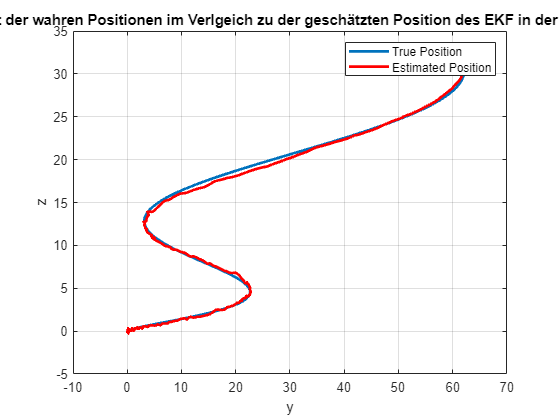


figure(1);
plot(R_pos(2,:), R_pos(3,:), 'LineWidth', 2);
hold on;
plot(estimated_position(2, :), estimated_position(3, :), 'r', 'LineWidth', 2);
hold off;
xlabel('y');
ylabel('z');
grid on;
title('3D-Plot der wahren Positionen im Verlgeich zu der geschätzten Position des EKF in der yz Ebene:');
legend('True Position', 'Estimated Position');

function obs = calculate_observations(x_k, pos_radar)
    
    dist_matrix_radar1 = [];
    phi_radar1 = [];
    theta_radar1 = [];

    R_transposed = transpose(x_k);
    for i=1:length(R_transposed(:,1))
        dist_radar1 = norm(R_transposed(1:3) - pos_radar);  % Berechnet den Abstand zwischen der i-ten Zeile von R_transposed und pos_radar
        dist_matrix_radar1 = [dist_matrix_radar1; dist_radar1]; 
        % Berechnung des Elevationswinkels (phi) für Radar 1
        delta_z = R_transposed(3) - pos_radar(3);
        rho = sqrt((R_transposed(1) - pos_radar(1))^2 + (R_transposed(2) - pos_radar(2))^2 + delta_z^2);
        phi_radar1 = [phi_radar1;rad2deg(acos(delta_z/rho))];  % Fügt den Winkel zu phi_radar1 hinzu
        
        % Berechnung des Azimutwinkels (theta) für Radar 1
        delta_x = R_transposed(1) - pos_radar(1);
        delta_y = R_transposed(2) - pos_radar(2);
        theta_radar1 = [theta_radar1; rad2deg(atan2(delta_y, delta_x))];  % Fügt den Winkel zu theta_radar1 hinzu
    end 



    polar_koordinaten_radar1 = [dist_matrix_radar1, theta_radar1, phi_radar1];
    
    obs = transpose(polar_koordinaten_radar1);

end


function H = create_observation_matrix(x_k, pos_radar1, pos_radar2)
    H = zeros(6, 6);
    H(1:3, 1:3) = eye(3);
    H(4:6, 4:6) = eye(3);

    obs_radar1 = calculate_observations(x_k, pos_radar1);
    obs_radar2 = calculate_observations(x_k, pos_radar2);

    % Beobachtung 1 (Abstand zu pos_radar1)
    dxyz = x_k(1:3, 1)' - pos_radar1;
    H(1, 1:3) = dxyz / obs_radar1(1);

    % Beobachtung 2 (Azimutwinkel zu pos_radar1)
    dxy = dxyz(1:2);
    H(2, 1:2) = [-dxy(2), dxy(1)] / norm(dxy)^2;

    % Beobachtung 3 (Elevationswinkel zu pos_radar1)
    H(3, 1:3) = [-dxy(1)*dxyz(3), -dxy(2)*dxyz(3), norm(dxy)^2] / (obs_radar1(3) * norm(dxyz)^3);

    % Beobachtung 4 (Abstand zu pos_radar2)
    dxyz = x_k(1:3, 1)' - pos_radar2;
    H(4, 1:3) = dxyz / obs_radar2(1);

    % Beobachtung 5 (Azimutwinkel zu pos_radar2)
    dxy = dxyz(1:2);
    H(5, 1:2) = [-dxy(2), dxy(1)] / norm(dxy)^2;

    % Beobachtung 6 (Elevationswinkel zu pos_radar2)
    H(6, 1:3) = [-dxy(1)*dxyz(3), -dxy(2)*dxyz(3), norm(dxy)^2] / (obs_radar2(3) * norm(dxyz)^3);
end


function kartesische_koordinaten_radar = get_kartesische_Koordianten(polar_koordinaten_radar)
    
    polar_koordinaten_radar = transpose(polar_koordinaten_radar);
    x_list1 = [];
    y_list1 = [];
    z_list1 = [];
    x_list2 = [];
    y_list2 = [];
    z_list2 = [];
    

    for i = 1:length(polar_koordinaten_radar(:,1))
        % Berechnung der kartesischen Koordinaten für Radar 1
        x_radar1 = polar_koordinaten_radar(i, 1) .* sin(deg2rad(polar_koordinaten_radar(i, 3))) .* cos(deg2rad(polar_koordinaten_radar(i, 2)));
        y_radar1 = polar_koordinaten_radar(i, 1) .* sin(deg2rad(polar_koordinaten_radar(i, 3))) .* sin(deg2rad(polar_koordinaten_radar(i, 2)));
        z_radar1 = polar_koordinaten_radar(i, 1) .* cos(deg2rad(polar_koordinaten_radar(i, 3)));
        x_list1 = [x_list1; x_radar1];
        y_list1 = [y_list1; (y_radar1-10)];
        z_list1 = [z_list1; z_radar1];

        
        % Berechnung der kartesischen Koordinaten für Radar 2
        x_radar2 = polar_koordinaten_radar(i, 4) .* sin(deg2rad(polar_koordinaten_radar(i, 6))) .* cos(deg2rad(polar_koordinaten_radar(i, 5)));
        y_radar2 = polar_koordinaten_radar(i, 4) .* sin(deg2rad(polar_koordinaten_radar(i, 6))) .* sin(deg2rad(polar_koordinaten_radar(i, 5)));
        z_radar2 = polar_koordinaten_radar(i, 4) .* cos(deg2rad(polar_koordinaten_radar(i, 6)));
        x_list2 = [x_list2; (x_radar2 -50)];
        y_list2 = [y_list2; (y_radar2 +30)];
        z_list2 = [z_list2; z_radar2];

    end
    % Kombinieren der kartesischen Koordinaten für Radar 1
    kartesische_koordinaten = [x_list1, y_list1, z_list1, x_list2, y_list2, z_list2];
    kartesische_koordinaten_radar = transpose(kartesische_koordinaten);


end